## **Limpiar variables**

 
clear

## Valores iniciales

**Posición del robot**

x = 0;
y = 0;
z = 0;
p_robot = [x; y; z];

**Orientación del robot**

phi = 0;    %Rotación en el eje X
theta = 0;  %Rotación en el eje Y
psi = 0;    %Rotación en el eje Z
ori_robot = deg2rad([phi; theta; psi]);
secuencia = "XYZ";

**Matriz de transformación homogenea inicial**

R_inicial = euler2rotMat(ori_robot,secuencia);
A0 = [R_inicial  p_robot
      zeros(1,3) 1];

**Crear estructura del robot en base a la tabla DH y los valores iniciales**

dh = readtable('datos\tabla_DH\robot1.csv');
robot = crear_robot(dh,A0);

**Trayectoria cartesiana del robot**

p = readtable("datos\trayectorias\cargar_trayectoria_1.csv");
n = length(p.x);
R_puntos = zeros(3,3,n);
for i = 1:n
    euler_puntos = deg2rad([p.phi(i);p.theta(i);p.psi(i)]);
    R_puntos(:,:,i) = euler2rotMat(euler_puntos,secuencia);
end
pos_puntos = [p.x';p.y';p.z'];
z_puntos = R_puntos(:,3,:);
 

## **Cinemática inversa de los puntos**

tol = 1e-6;
max_iter = 100;
alpha = 1.0;
numSamples = 9; % Esto sirve para buscar diferentes puntos en caso de llegar a un mínimo local
q_sol = zeros(robot.NGDL,n);
p_sol = zeros(size(pos_puntos));
for i = 1:n
%     [q_sol(:,i),p_sol(:,i)] = cinematica_inv(robot, pos_puntos(:,i), z_puntos(:,i), tol, max_iter, alpha, numSamples); % Con rotación
    [q_sol(:,i),p_sol(:,i)] = cinematica_inv(robot, pos_puntos(:,i), tol, max_iter, alpha, numSamples);
end

Solución alcanzada en muestra 1, iteraciones 3, error = 4.443409e-11
Solución alcanzada en muestra 1, iteraciones 4, error = 4.984661e-11


## **Trayectoria de punto articular a punto articular**

% Calcular la diferencia entre la configuración final y la inicial para cada junta
delta_q = abs(q_sol(:,2) - q_sol(:,1));
% Usar el valor más alto de los tiempos mínimos requeridos para cada junta,
% de forma que siempre sea un perfil triangular.
t_final = max(2 * delta_q ./ robot.dqMax);
% Muestras para graficar trayectoria
numSamples = 201;

[q, dq, ddq, t, pp] = trapveltraj(q_sol, numSamples, ...
                                            'Acceleration', robot.ddqMax, ...
                                            'EndTime', t_final);

## Cinemática diferencial

**Inicializar variables**

posicion = zeros(3,length(t));
orientacion = posicion;
vel_linear = posicion;
vel_angular = posicion;
acel_linear = posicion;
acel_angular = posicion;
R = zeros(3,3,length(t));
Jv = zeros(3,robot.NGDL,length(t));
dJv = Jv;
Jw = Jv;
dJw = Jw;

**Calcular velocidad y aceleración**

Algo que cabe destacar es que se realizarán cálculos discretos, por lo que en vez de una función $f\left(t\right)$, donde podemos sustiruir por ejemplo $t=2s$, aquí usaremos los índices $k$, los  cuales se refieren a los índices del vector de tiempo que corresponden al tiempo actual $t\left(k\right)$, a un tiempo anterior $t\left(k-1\right)$ o al tiempo siguiente $t\left(k+1\right)$.

for k = 1:length(t)

**            Actualiza la configuración del robot con los valores articulares **$q\left(k\right)$

    robot = actualizar_robot_completo(robot, q(:,k));

**            Extraer la posición y orientación del efector final**

    posicion(:,k) = robot.T(1:3,4,end);
    R(:,:,k) = robot.T(1:3,1:3,end);

**            Obtener la orientación en ángulos de Euler a partir de la matriz R del efector final**

    orientacion(:,k) = rotMat2euler(R(:, :, k),secuencia);

**            Calcular el Jacobiano geométrico a partir de la transformación global**

    [Jv(:,:,k),Jw(:,:,k)] = jac_geometrico_completo(robot);

**            Calcular la velocidad lineal y angular**

####             
$$v=J\dot{q}$$


    vel_linear(:,k)  = Jv(:,:,k)*dq(:,k);
    vel_angular(:,k) = Jw(:,:,k)*dq(:,k);

**            Calcular la derivada temporal del Jacobiano usando diferencias finitas**

    if k > 1
        dt = t(k) - t(k-1);
        dJv(:,:,k) = (Jv(:,:,k) - Jv(:,:,k-1)) / dt;
        dJw(:,:,k) = (Jw(:,:,k) - Jw(:,:,k-1)) / dt;
    end

**            Calcular la aceleración lineal y angular**

####             
$$a=\frac{d}{\textrm{dt}}\left(J\dot{q} \right)=J\ddot{q} +\dot{J} \dot{q}$$


    acel_linear(:,k) = Jv(:,:,k)*ddq(:,k) + dJv(:,:,k)*dq(:,k);
    acel_angular(:,k) = Jw(:,:,k)*ddq(:,k) + dJw(:,:,k)*dq(:,k);
end

## Animación

Si solo vas a imprimir la gráfica, debes usar 30 fps (la mitad de los que dice la gráfica).

close all
fps = 30;

t_animacion = 0:1/fps:t_final;
animSamples = length(t_animacion);

**Crear estructura gráfica del robot**

g = crear_grafica_robot();

**Generar el nombre del archivo con fecha y hora actual**

nombre_video = sprintf('resultados/animaciones/cinematica_directa_robot1_%s.avi', datestr(now, 'yyyy-mm-dd_HH-MM-SS'));

**Comenta las siguientes lineas si no quieres generar el video**

% videoObj = VideoWriter(nombre_video);
% videoObj.FrameRate = fps;
% open(videoObj);

**Generar animación**

q_anim = zeros(robot.NGDL,1);
for k = 1:length(t_animacion)
% for k = 1:n
%     robot = actualizar_robot(robot, q_anim(:,k));
    for i = 1:robot.NGDL
        q_anim(i) = ppval(cell2mat(pp(i)),t_animacion(k));
    end
    robot = actualizar_robot_completo(robot, q_anim);
    g = dibujar_robot(g, robot);
    

**            Capturar el fotograma actual y escribirlo en el video (comenta si no quieres generar video)**

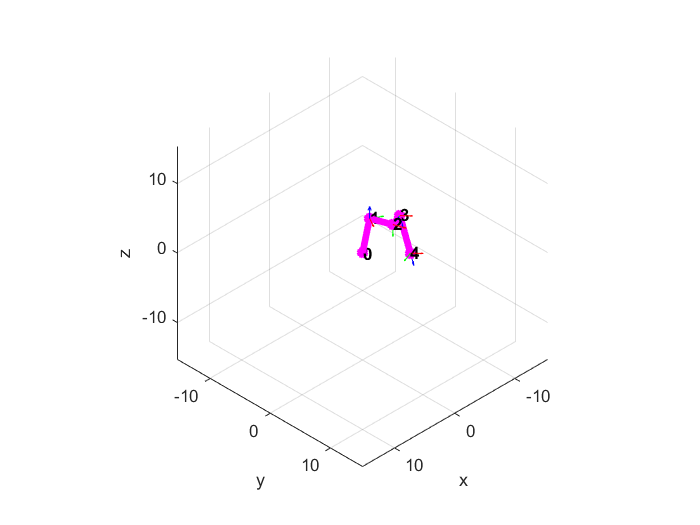

%     frame = getframe(gcf);
%     writeVideo(videoObj, frame);
end

## **Gráficas**

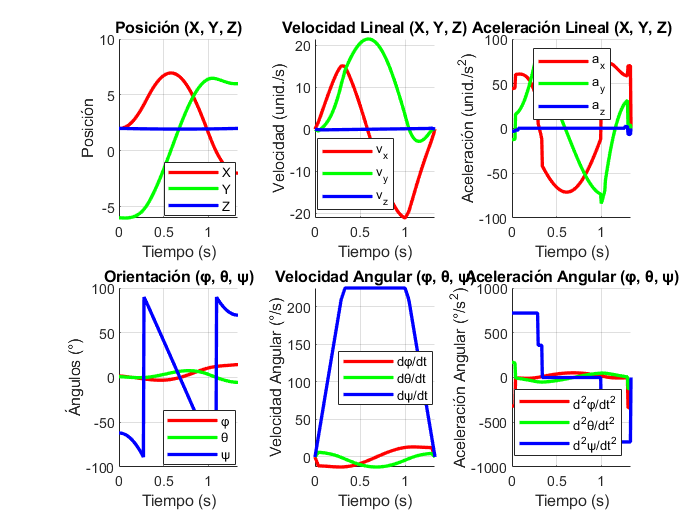

figure;

% --- Primera fila: Cinemática lineal ---

% 1. Posición
subplot(2,3,1);
hold on; grid on;
plot(t, posicion(1,:), 'r', 'LineWidth', 2); % Componente X en rojo
plot(t, posicion(2,:), 'g', 'LineWidth', 2); % Componente Y en verde
plot(t, posicion(3,:), 'b', 'LineWidth', 2); % Componente Z en azul
title('Posición (X, Y, Z)');
xlabel('Tiempo (s)'); ylabel('Posición');
legend('X', 'Y', 'Z', 'Location', 'Best');

% 2. Velocidad lineal
subplot(2,3,2);
hold on; grid on;
plot(t, vel_linear(1,:), 'r', 'LineWidth', 2);
plot(t, vel_linear(2,:), 'g', 'LineWidth', 2);
plot(t, vel_linear(3,:), 'b', 'LineWidth', 2);
title('Velocidad Lineal (X, Y, Z)');
xlabel('Tiempo (s)'); ylabel('Velocidad (unid./s)');
legend('v_x', 'v_y', 'v_z', 'Location', 'Best');

% 3. Aceleración lineal
subplot(2,3,3);
hold on; grid on;
plot(t, acel_linear(1,:), 'r', 'LineWidth', 2);
plot(t, acel_linear(2,:), 'g', 'LineWidth', 2);
plot(t, acel_linear(3,:), 'b', 'LineWidth', 2);
title('Aceleración Lineal (X, Y, Z)');
xlabel('Tiempo (s)'); ylabel('Aceleración (unid./s^2)');
legend('a_x', 'a_y', 'a_z', 'Location', 'Best');

% --- Segunda fila: Cinemática angular ---
orientacion_deg = rad2deg(orientacion);
% 4. Orientación
subplot(2,3,4);
hold on; grid on;
plot(t, orientacion_deg(1,:), 'r', 'LineWidth', 2);
plot(t, orientacion_deg(2,:), 'g', 'LineWidth', 2);
plot(t, orientacion_deg(3,:), 'b', 'LineWidth', 2);
title('Orientación (φ, θ, ψ)');
xlabel('Tiempo (s)'); ylabel('Ángulos (°)');
legend('φ', 'θ', 'ψ', 'Location', 'Best');

vel_angular_deg = rad2deg(vel_angular);
% 5. Velocidad angular
subplot(2,3,5);
hold on; grid on;
plot(t, vel_angular_deg(1,:), 'r', 'LineWidth', 2);
plot(t, vel_angular_deg(2,:), 'g', 'LineWidth', 2);
plot(t, vel_angular_deg(3,:), 'b', 'LineWidth', 2);
title('Velocidad Angular (φ, θ, ψ)');
xlabel('Tiempo (s)'); ylabel('Velocidad Angular (°/s)');
legend('dφ/dt', 'dθ/dt', 'dψ/dt', 'Location', 'Best');

acel_angular_deg = rad2deg(acel_angular);
% 6. Aceleración angular
subplot(2,3,6);
hold on; grid on;
plot(t, acel_angular_deg(1,:), 'r', 'LineWidth', 2);
plot(t, acel_angular_deg(2,:), 'g', 'LineWidth', 2);
plot(t, acel_angular_deg(3,:), 'b', 'LineWidth', 2);
title('Aceleración Angular (φ, θ, ψ)');
xlabel('Tiempo (s)'); ylabel('Aceleración Angular (°/s^2)');
legend('d^2φ/dt^2', 'd^2θ/dt^2', 'd^2ψ/dt^2', 'Location', 'Best');

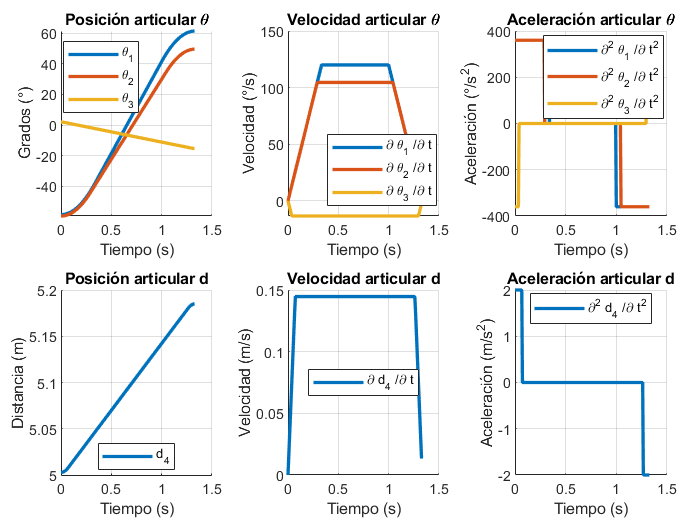


% --- Cinemática articular ---
figure;

% Determinar el número de filas: 1 si todas son del mismo tipo, 2 si hay mezcla
if all(robot.tipo == 'r') || all(robot.tipo == 'p')
    numRows = 1;
else
    numRows = 2;
end
numCols = 3; % Posición, velocidad y aceleración

% Configurar el layout de la figura
tiledlayout(numRows, numCols, 'TileSpacing', 'Compact', 'Padding', 'Compact');

% Copias para graficar (convertir a grados para juntas revolutas)
qplot = q;
dqplot = dq;
ddqplot = ddq;
for i = 1:robot.NGDL
    if robot.tipo(i) == 'r'
        qplot(i,:) = rad2deg(q(i,:));
        dqplot(i,:) = rad2deg(dq(i,:));
        ddqplot(i,:) = rad2deg(ddq(i,:));
    end
end

% Iterar sobre cada junta
for i = 1:robot.NGDL
    % Asignar parámetros según el tipo de articulación
    if robot.tipo(i) == 'r'
        row = 1;
        qName = ['\theta_' num2str(i)];
        titleName = '\theta';
        unidad_q = 'Grados (°)';
        unidad_dq = 'Velocidad (°/s)';
        unidad_ddq = 'Aceleración (°/s^2)';
    else  % 'p'
        row = 2;
        qName = ['d_' num2str(i)];
        titleName = 'd';
        unidad_q = 'Distancia (m)';
        unidad_dq = 'Velocidad (m/s)';
        unidad_ddq = 'Aceleración (m/s^2)';
    end
    
    % Calcular el índice de la celda en el layout: las celdas se enumeran de izquierda a derecha
    % en cada fila. Por ejemplo, para la fila 1: celdas 1, 2, 3; para la fila 2: 4, 5, 6.
    idxPos = (row-1)*numCols + 1; % posición
    idxVel = (row-1)*numCols + 2; % velocidad
    idxAcel = (row-1)*numCols + 3; % aceleración
    
    % Gráfica de posición
    nexttile(idxPos);
    hold on; grid on;
    plot(t(1:end-1), qplot(i,1:end-1), 'LineWidth', 2, 'DisplayName', qName);
    title(['Posición articular ' titleName]);
    xlabel('Tiempo (s)'); ylabel(unidad_q);
    legend('Location', 'best');
    
    % Gráfica de velocidad
    nexttile(idxVel);
    hold on; grid on;
    dqName = ['\partial ' qName ' /\partial t'];
    plot(t(1:end-1), dqplot(i,1:end-1), 'LineWidth', 2, 'DisplayName', dqName);
    title(['Velocidad articular ' titleName]);
    xlabel('Tiempo (s)'); ylabel(unidad_dq);
    legend('Location', 'best');
    
    % Gráfica de aceleración
    nexttile(idxAcel);
    hold on; grid on;
    ddqName = ['\partial^2 ' qName ' /\partial t^2'];
    plot(t(1:end-1), ddqplot(i,1:end-1), 'LineWidth', 2, 'DisplayName', ddqName);
    title(['Aceleración articular ' titleName]);
    xlabel('Tiempo (s)'); ylabel(unidad_ddq);
    legend('Location', 'best');
end


% Ajustar apariencia de la figura
set(gcf, 'Color', 'w');
